## Set up the Import Options and import the data

clear; close all; clc
opts = spreadsheetImportOptions("NumVariables", 9);

% Specify sheet and range
opts.Sheet = "full_fact";
opts.DataRange = "B2:J37";

% Specify column names and types
opts.VariableNames = ["FM", "FD", "H", "AT", "tr", "tf_66","tf_50","tf_66_a","tf_50_a"];
opts.VariableTypes = ["categorical", "categorical", "categorical", "categorical", "double", "double", "double", "double", "double"];

% Specify variable properties
%opts = setvaropts(opts, ["Replicates", "D", "E", "VarName7"], "EmptyFieldRule", "auto");

% Import the data
data_full_fact = readtable("/Users/cyrilmonette/Desktop/EPFL 2018-2026/PhD - Mobots/ENG-606/project/RoboticFrameCharacterisation/data.xlsx", opts, "UseExcel", false)

data_full_fact = 36×9 table
     FM        FD        H         AT         tr      tf_66     tf_50     tf_66_a    tf_50_a
    _____    ______    ______    _______    ______    ______    ______    _______    _______

    Water    Low       edge      Indoors    1.8333    5.3333       2.5      5.25        2.5 
    Water    Low       middle    Indoors    1.9167    8.8333    3.0833    10.583        3.5 
    Water    Medium    edge      Indoors    2.0833    4.0833    1.9167      4.25          2 
    Water    Medium    middle    Indoors    2.3333    9.6667    3.0833    10.083     3.3333 
    Water    High      edge      Indoors    2.4167    7.8333    2.3333    7.4167     2.3333 
    Water    H

clear opts % Clearing temporary variables

## Constant coeff models

% 5=tr    6=tf_66     7=tf_50   8=tf_66_a   9=tf_50_a   
response_ix = 7; % change here to switch response
mu=grpstats(data_full_fact{:,response_ix})

mu = 2.8843

temp_matrix = data_full_fact;
temp_matrix{:,response_ix} = data_full_fact{:,response_ix}-mu

temp_matrix = 36×9 table
     FM        FD        H         AT         tr      tf_66      tf_50      tf_66_a    tf_50_a
    _____    ______    ______    _______    ______    ______    ________    _______    _______

    Water    Low       edge      Indoors    1.8333    5.3333    -0.38426      5.25        2.5 
    Water    Low       middle    Indoors    1.9167    8.8333     0.19907    10.583        3.5 
    Water    Medium    edge      Indoors    2.0833    4.0833    -0.96759      4.25          2 
    Water    Medium    middle    Indoors    2.3333    9.6667     0.19907    10.083     3.3333 
    Water    High      edge      Indoors    2.4167    7.8333    -0.55093    7.4167     2.3333 
   


% Main effects:
FMMeans=grpstats(temp_matrix(:,[1 response_ix]),{'FM'})

FMMeans = 3×3 table
              FM      GroupCount    mean_tf_50
             _____    __________    __________

    Bees     Bees         12          0.78935 
    Honey    Honey        12         -0.36343 
    Water    Water        12         -0.42593 


FDMeans=grpstats(temp_matrix(:,[2 response_ix]),{'FD'});
FDMeans = FDMeans([2 3 1],:) % To re-order

FDMeans = 3×3 table
                FD      GroupCount    mean_tf_50
              ______    __________    __________

    Low       Low           12            0.1713
    Medium    Medium        12        -0.0023148
    High      High          12          -0.16898


HMeans = grpstats(temp_matrix(:,[3 response_ix]),{'H'})

HMeans = 2×3 table
                H       GroupCount    mean_tf_50
              ______    __________    __________

    edge      edge          18         -0.2037  
    middle    middle        18          0.2037  


ATMeans = grpstats(temp_matrix(:,[4 response_ix]),{'AT'})

ATMeans = 2×3 table
                   AT       GroupCount    mean_tf_50
                ________    __________    __________

    Indoors     Indoors         18         0.087963 
    Outdoors    Outdoors        18        -0.087963 



% Produce estimates with the model y ~ mu + main effects
Estimates1= zeros(36,1);
for i=1:36
    FM_effect = FMMeans{string(data_full_fact{i,'FM'}),3};
    FD_effect = FDMeans{string(data_full_fact{i,'FD'}),3};
    H_effect = HMeans{string(data_full_fact{i,'H'}),3};
    AT_effect = ATMeans{string(data_full_fact{i,'AT'}),3};
    Estimates1(i) = mu + FM_effect + FD_effect + H_effect + AT_effect;
end

% Two-way mixed effects:
% First we remove the main effects from temp_matrix
for i=1:3 % Removing FM
    temp_matrix{:,response_ix}=temp_matrix{:,response_ix}-FMMeans{i,3}*(temp_matrix{:,1}==FMMeans{i,1});
end
for i=1:3 % Removing FD
    temp_matrix{:,response_ix}=temp_matrix{:,response_ix}-FDMeans{i,3}*(temp_matrix{:,2}==FDMeans{i,1});
end
for i=1:2 % Removing H
    temp_matrix{:,response_ix}=temp_matrix{:,response_ix}-HMeans{i,3}*(temp_matrix{:,3}==HMeans{i,1});
end
for i=1:2 % Removing AT
    temp_matrix{:,response_ix}=temp_matrix{:,response_ix}-ATMeans{i,3}*(temp_matrix{:,4}==ATMeans{i,1});
end

% Then we compute the two-way mixed effects

FM_FD = grpstats(temp_matrix(:,[1 2 response_ix]),{'FM','FD'})

FM_FD = 9×4 table
                     FM        FD      GroupCount    mean_tf_50
                    _____    ______    __________    __________

    Bees_High       Bees     High          4          0.016204 
    Bees_Low        Bees     Low           4         -0.094907 
    Bees_Medium     Bees     Medium        4          0.078704 
    Honey_High      Honey    High          4         -0.081019 
    Honey_Low       Honey    Low           4          0.078704 
    Honey_Medium    Honey    Medium        4         0.0023148 
    Water_High      Water    High          4          0.064815 
    Water_Low       Water    Low           4          0.016204 
    Water_Medium    Water    Medium        4        

FM_H = grpstats(temp_matrix(:,[1 3 response_ix]),{'FM','H'});
FM_AT = grpstats(temp_matrix(:,[1 4 response_ix]),{'FM','AT'});
FD_H = grpstats(temp_matrix(:,[2 3 response_ix]),{'FD','H'});
FD_AT = grpstats(temp_matrix(:,[2 4 response_ix]),{'FD','AT'});
H_AT = grpstats(temp_matrix(:,[3 4 response_ix]),{'H','AT'});

% Produce estimates with the model y ~ mu + main effects
% Estimates2= zeros(36,1)
% for i=1:36
%     FM_FD_effect = FM_FD{string(data_full_fact{i,'FM'})+"_"+string(data_full_fact{i,'FD'}),4}
%     FM_H_effect = FM_FD{string(data_full_fact{i,'FM'})+"_"+string(data_full_fact{i,'FD'}),4}
%     Estimates1(i) = mu + 
% end

% Three-way mixed effects:
% First we remove the effect of mixed effects from temp_matrix
residuals_before_mixed = temp_matrix{:,response_ix}

residuals_before_mixed =    -0.0139
    0.1620
   -0.4236
    0.3356
    0.1597
    0.3356
   -0.7292
   -0.8866
    0.2778
   -0.0463


for i=1:length(temp_matrix{:,response_ix}) % Removing FM_FD
    %First we find the row in FM_FD that matches the FM and FD of index i
    row = find( arrayfun(@(RIDX) FM_FD{RIDX,'FM'}== temp_matrix{i,'FM'} && FM_FD{RIDX,'FD'}==temp_matrix{i,'FD'}, 1:size(FM_FD,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FM_FD{row,4}; % column 4 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FM_H
    %First we find the row in FM_H that matches the FM and H of index i
    row = find( arrayfun(@(RIDX) FM_H{RIDX,'FM'}== temp_matrix{i,'FM'} && FM_H{RIDX,'H'}==temp_matrix{i,'H'}, 1:size(FM_H,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FM_H{row,4}; %  column 4 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FM_AT
    %First we find the row in FM_AT that matches the FM and AT of index i
    row = find( arrayfun(@(RIDX) FM_AT{RIDX,'FM'}== temp_matrix{i,'FM'} && FM_AT{RIDX,'AT'}==temp_matrix{i,'AT'}, 1:size(FM_AT,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FM_AT{row,4}; %  column 4 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FD_H
    %First we find the row in FD_H that matches the FD and H of index i
    row = find( arrayfun(@(RIDX) FD_H{RIDX,'FD'}== temp_matrix{i,'FD'} && FD_H{RIDX,'H'}==temp_matrix{i,'H'}, 1:size(FD_H,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FD_H{row,4}; %  column 4 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FD_AT
    %First we find the row in FD_AT that matches the FD and AT of index i
    row = find( arrayfun(@(RIDX) FD_AT{RIDX,'FD'}== temp_matrix{i,'FD'} && FD_AT{RIDX,'AT'}==temp_matrix{i,'AT'}, 1:size(FD_AT,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FD_AT{row,4}; %  column 4 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing H_AT
    %First we find the row in H_AT that matches the H and AT of index i
    row = find( arrayfun(@(RIDX) H_AT{RIDX,'H'}== temp_matrix{i,'H'} && H_AT{RIDX,'AT'}==temp_matrix{i,'AT'}, 1:size(H_AT,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-H_AT{row,4}; %  column 4 is mean_tr (or mean/tf, etc.)
end
residuals_after_2way = temp_matrix{:,response_ix}

residuals_after_2way =     0.2014
   -0.0116
   -0.4444
    0.1898
    0.0486
    0.0162
   -0.1944
   -0.4491
    0.3056
    0.1481



% Now we compute the three-way mixed effects:
FM_FD_H = grpstats(temp_matrix(:,[1 2 3 response_ix]),{'FM','FD', 'H'})

FM_FD_H = 18×5 table
                            FM        FD        H       GroupCount    mean_tf_50
                           _____    ______    ______    __________    __________

    Bees_High_edge         Bees     High      edge          2          -0.016204
    Bees_High_middle       Bees     High      middle        2           0.016204
    Bees_Low_edge          Bees     Low       edge          2           0.011574
    Bees_Low_middle        Bees     Low       middle        2          -0.011574
    Bees_Medium_edge       Bees     Medium    edge          2          0.0046296
    Bees_Medium_middle     Bees     Medium    middle        2         -0.0046296
    Honey_High_edge        Honey    High 

FM_FD_AT = grpstats(temp_matrix(:,[1 2 4 response_ix]),{'FM','FD', 'AT'})

FM_FD_AT = 18×5 table
                              FM        FD         AT       GroupCount    mean_tf_50
                             _____    ______    ________    __________    __________

    Bees_High_Indoors        Bees     High      Indoors         2          0.094907 
    Bees_High_Outdoors       Bees     High      Outdoors        2         -0.094907 
    Bees_Low_Indoors         Bees     Low       Indoors         2          -0.32176 
    Bees_Low_Outdoors        Bees     Low       Outdoors        2           0.32176 
    Bees_Medium_Indoors      Bees     Medium    Indoors         2           0.22685 
    Bees_Medium_Outdoors     Bees     Medium    Outdoors        2          -0.22685 
    Honey_High_In

FM_H_AT = grpstats(temp_matrix(:,[1 3 4 response_ix]),{'FM','H', 'AT'})

FM_H_AT = 12×5 table
                              FM        H          AT       GroupCount    mean_tf_50
                             _____    ______    ________    __________    __________

    Bees_edge_Indoors        Bees     edge      Indoors         3            0.06713
    Bees_edge_Outdoors       Bees     edge      Outdoors        3           -0.06713
    Bees_middle_Indoors      Bees     middle    Indoors         3           -0.06713
    Bees_middle_Outdoors     Bees     middle    Outdoors        3            0.06713
    Honey_edge_Indoors       Honey    edge      Indoors         3         -0.0023148
    Honey_edge_Outdoors      Honey    edge      Outdoors        3          0.0023148
    Honey_middle_I

FD_H_AT = grpstats(temp_matrix(:,[2 3 4 response_ix]),{'FD','H', 'AT'})

FD_H_AT = 12×5 table
                                FD        H          AT       GroupCount    mean_tf_50
                              ______    ______    ________    __________    __________

    High_edge_Indoors         High      edge      Indoors         3           0.011574
    High_edge_Outdoors        High      edge      Outdoors        3          -0.011574
    High_middle_Indoors       High      middle    Indoors         3          -0.011574
    High_middle_Outdoors      High      middle    Outdoors        3           0.011574
    Low_edge_Indoors          Low       edge      Indoors         3          0.0046296
    Low_edge_Outdoors         Low       edge      Outdoors        3         -0.0046296
    


% And we remove them from temp_matrix:
for i=1:length(temp_matrix{:,response_ix}) % Removing FM_FD_H
    %First we find the row in FM_FD_H that matches the FM, FD and H of index i
    row = find( arrayfun(@(RIDX) FM_FD_H{RIDX,'FM'}== temp_matrix{i,'FM'} && FM_FD_H{RIDX,'FD'}==temp_matrix{i,'FD'} && FM_FD_H{RIDX,'H'}==temp_matrix{i,'H'}, 1:size(FM_FD_H,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FM_FD_H{row,5}; % column 5 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FM_FD_AT
    %First we find the row in FM_FD_AT that matches the FM, FD and AT of index i
    row = find( arrayfun(@(RIDX) FM_FD_AT{RIDX,'FM'}== temp_matrix{i,'FM'} && FM_FD_AT{RIDX,'FD'}==temp_matrix{i,'FD'} && FM_FD_AT{RIDX,'AT'}==temp_matrix{i,'AT'}, 1:size(FM_FD_AT,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FM_FD_AT{row,5}; % column 5 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FM_H_AT
    %First we find the row in FM_H_AT that matches the FM, H and AT of index i
    row = find( arrayfun(@(RIDX) FM_H_AT{RIDX,'FM'}== temp_matrix{i,'FM'} && FM_H_AT{RIDX,'H'}==temp_matrix{i,'H'} && FM_H_AT{RIDX,'AT'}==temp_matrix{i,'AT'}, 1:size(FM_H_AT,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FM_H_AT{row,5}; % column 5 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FD_H_AT
    %First we find the row in FD_H_AT that matches the FD, H and AT of index i
    row = find( arrayfun(@(RIDX) FD_H_AT{RIDX,'FD'}== temp_matrix{i,'FD'} && FD_H_AT{RIDX,'H'}==temp_matrix{i,'H'} && FD_H_AT{RIDX,'AT'}==temp_matrix{i,'AT'}, 1:size(FD_H_AT,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FD_H_AT{row,5}; % column 5 is mean_tr (or mean/tf, etc.)
end
residuals_after_3way = temp_matrix{:,response_ix}

residuals_after_3way =    -0.0116
    0.0116
   -0.0949
    0.0949
    0.1065
   -0.1065
    0.0440
   -0.0440
    0.0231
   -0.0231


## Fitlm models

FM_col = reordercats(data_full_fact{:,"FM"},{'Bees','Honey','Water'});
FD_col = reordercats(data_full_fact{:,"FD"},{'Low','Medium','High'});
H_col = reordercats(data_full_fact{:,"H"},{'edge','middle'});
AT_col = reordercats(data_full_fact{:,"AT"},{'Outdoors','Indoors'});
data = data_full_fact;
data.FM = FM_col;
data.FD = FD_col;
data.H = H_col;
data.AT = AT_col;

main_effects_model = fitlm(data,'tr ~ FM + FD + H + AT','CategoricalVars',{'FM','FD','H','AT'})

main_effects_model = Linear regression model:
    tr ~ 1 + FM + FD + H + AT

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     1.1597     0.074594    15.547    1.3282e-15
    FM_Honey       0.36111      0.06906    5.2289    1.3425e-05
    FM_Water       0.59028      0.06906    8.5473    2.0454e-09
    FD_Medium      0.11111      0.06906    1.6089       0.11847
    FD_High        0.40278      0.06906    5.8323    2.5259e-06
    H_middle       0.24074     0.056387    4.2694    0.00019166
    AT_Indoors     0.16667     0.056387    2.9557     0.0061394


Number of observations: 36, Error degrees of freedom: 29
Root Mea

two_way_effects_model = fitlm(data,'tr ~ FM*FD + FM*H + FM*AT + FD*H + FD*AT + H*AT','CategoricalVars',{'FM','FD','H','AT'})

two_way_effects_model = Linear regression model:
    tr ~ 1 + FM*FD + FM*H + FD*H + FM*AT + FD*AT + H*AT

Estimated Coefficients:
                             Estimate         SE          tStat         pValue  
                            ___________    ________    ___________    __________

    (Intercept)                  1.3912    0.055507         25.063    2.8766e-14
    FM_Honey                    0.11806    0.067982         1.7366       0.10168
    FM_Water                      0.125    0.067982         1.8387      0.084592
    FD_Medium                 -0.048611    0.067982       -0.71506       0.48488
    FD_High                   -0.020833    0.067982       -0.30645       0.76321
    H_middle                    0.13426    0.060805          2.2

three_way_effects_model = fitlm(data,'tf_50 ~ FM*FD*H + FM*H*AT + FM*FD*AT + FD*H*AT','CategoricalVars',{'FM','FD','H','AT'})

three_way_effects_model = Linear regression model:
    tf_50 ~ 1 + FM*FD + FM*H + FD*H + FM*AT + FD*AT + H*AT + FM:FD:H + FM:FD:AT + FM:H:AT + FD:H:AT

Estimated Coefficients:
                                     Estimate       SE        tStat        pValue  
                                     _________    _______    ________    __________

    (Intercept)                          4.044     0.1769      22.861    2.1691e-05
    FM_Honey                           -1.9931    0.24223      -8.228     0.0011895
    FM_Water                           -1.7222    0.24223     -7.1099     0.0020677
    FD_Medium                         -0.60417    0.24223     -2.4942      0.067181
    FD_High                           -0.77778    0.24223     -3.2109       0.03256
    H_

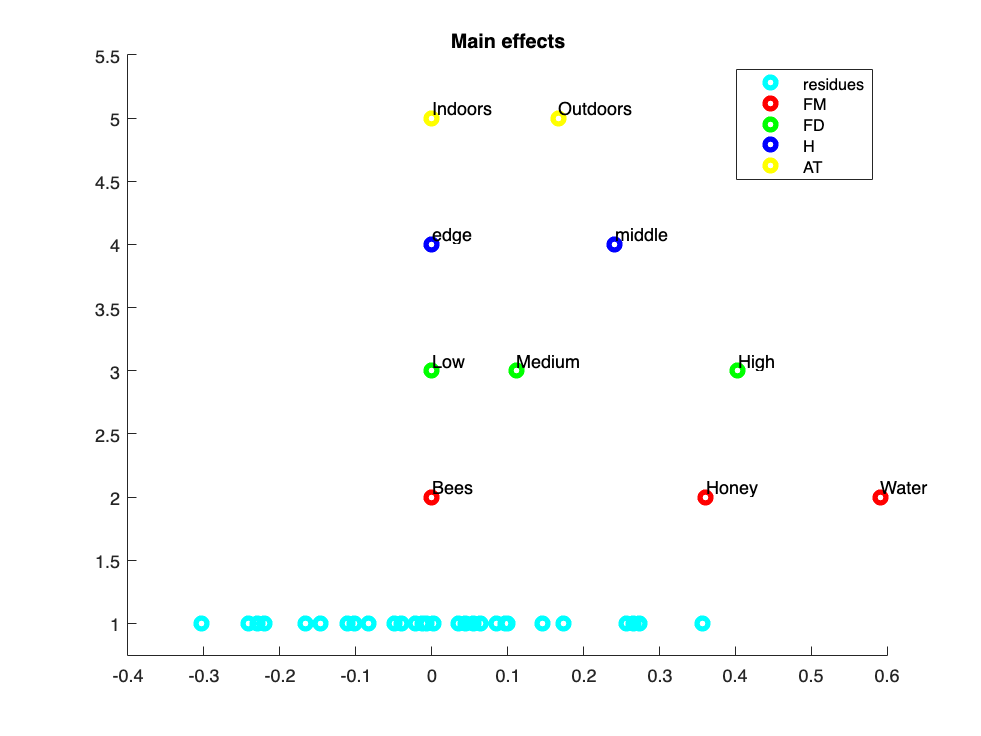

scatter(main_effects_model.Residuals{:,'Raw'},ones([1 height(residuals_before_mixed)]),"co","LineWidth",3)
hold on
scatter(vertcat(0, main_effects_model.Coefficients.Estimate(2:3)),2*ones([1 height(FMMeans)]),"ro","LineWidth",3)
scatter(vertcat(0, main_effects_model.Coefficients.Estimate(4:5)),3*ones([1 height(FMMeans)]),"go","LineWidth",3)
scatter(vertcat(0, main_effects_model.Coefficients.Estimate(6)),4*ones([1 height(HMeans)]),"bo","LineWidth",3)
scatter(vertcat(0, main_effects_model.Coefficients.Estimate(7)),5*ones([1 height(ATMeans)]),"yo","LineWidth",3)
hold off
ylim([0.75 5.5])
%xlim([-80 80])
legend(["residues" "FM" "FD" "H" "AT"])
title("Main effects")
% Add labels
text(vertcat(0, main_effects_model.Coefficients.Estimate(2:3)), 2*ones([1 height(FMMeans)]), categories(data{:,'FM'}), 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(vertcat(0, main_effects_model.Coefficients.Estimate(4:5)), 3*ones([1 height(FDMeans)]), FDMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(vertcat(0, main_effects_model.Coefficients.Estimate(6)), 4*ones([1 height(HMeans)]), HMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(vertcat(0, main_effects_model.Coefficients.Estimate(7)), 5*ones([1 height(ATMeans)]), ATMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)

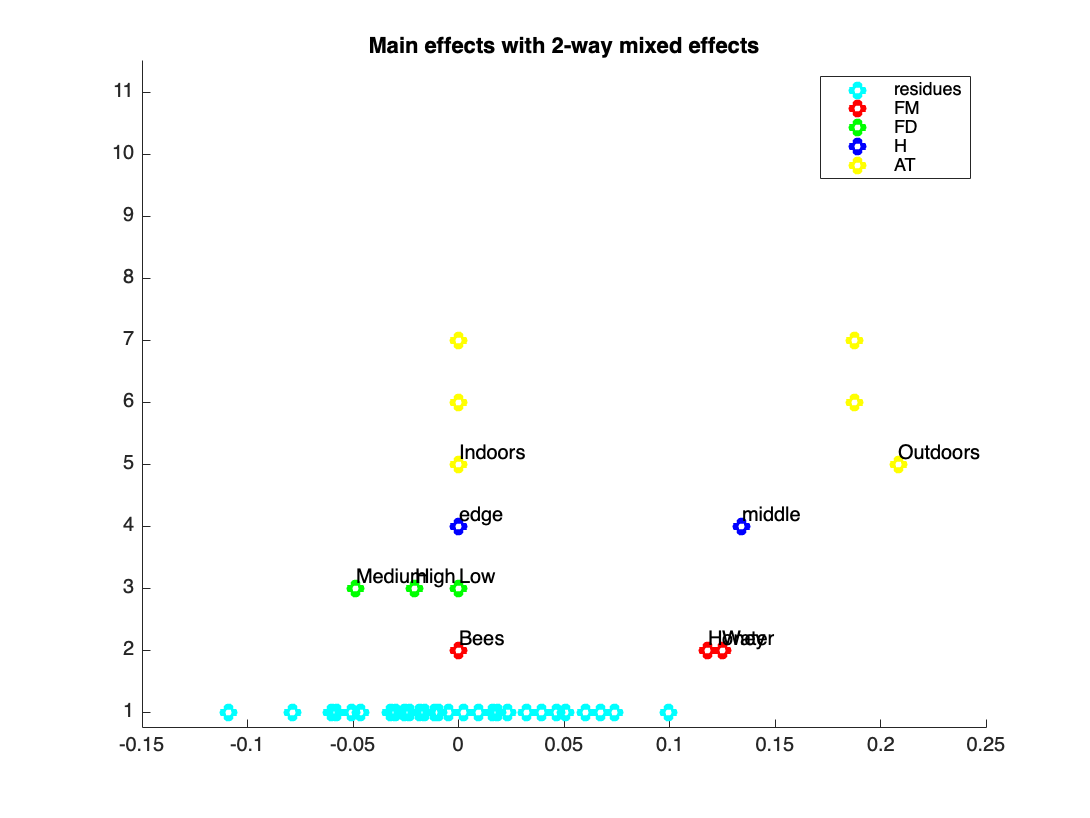



figure
scatter(two_way_effects_model.Residuals{:,'Raw'},ones([1 height(two_way_effects_model.Residuals{:,'Raw'})]),"co","LineWidth",3)
hold on
scatter(vertcat(0, two_way_effects_model.Coefficients.Estimate(2:3)),2*ones([1 height(FMMeans)]),"ro","LineWidth",3)
scatter(vertcat(0, two_way_effects_model.Coefficients.Estimate(4:5)),3*ones([1 height(FMMeans)]),"go","LineWidth",3)
scatter(vertcat(0, two_way_effects_model.Coefficients.Estimate(6)),4*ones([1 height(HMeans)]),"bo","LineWidth",3)
scatter(vertcat(0, two_way_effects_model.Coefficients.Estimate(7)),5*ones([1 height(ATMeans)]),"yo","LineWidth",3)
scatter(vertcat(0, two_way_effects_model.Coefficients.Estimate(8)),6*ones([1 height(ATMeans)]),"yo","LineWidth",3)
scatter(vertcat(0, two_way_effects_model.Coefficients.Estimate(8)),7*ones([1 height(ATMeans)]),"yo","LineWidth",3)


hold off
ylim([0.75 11.5])
legend(["residues" "FM" "FD" "H" "AT"])
title("Main effects with 2-way mixed effects")
% Add labels
text(vertcat(0, two_way_effects_model.Coefficients.Estimate(2:3)), 2*ones([1 height(FMMeans)]), categories(data{:,'FM'}), 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(vertcat(0, two_way_effects_model.Coefficients.Estimate(4:5)), 3*ones([1 height(FDMeans)]), FDMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(vertcat(0, two_way_effects_model.Coefficients.Estimate(6)), 4*ones([1 height(HMeans)]), HMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(vertcat(0, two_way_effects_model.Coefficients.Estimate(7)), 5*ones([1 height(ATMeans)]), ATMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)

## Dot Plot without mixed effects

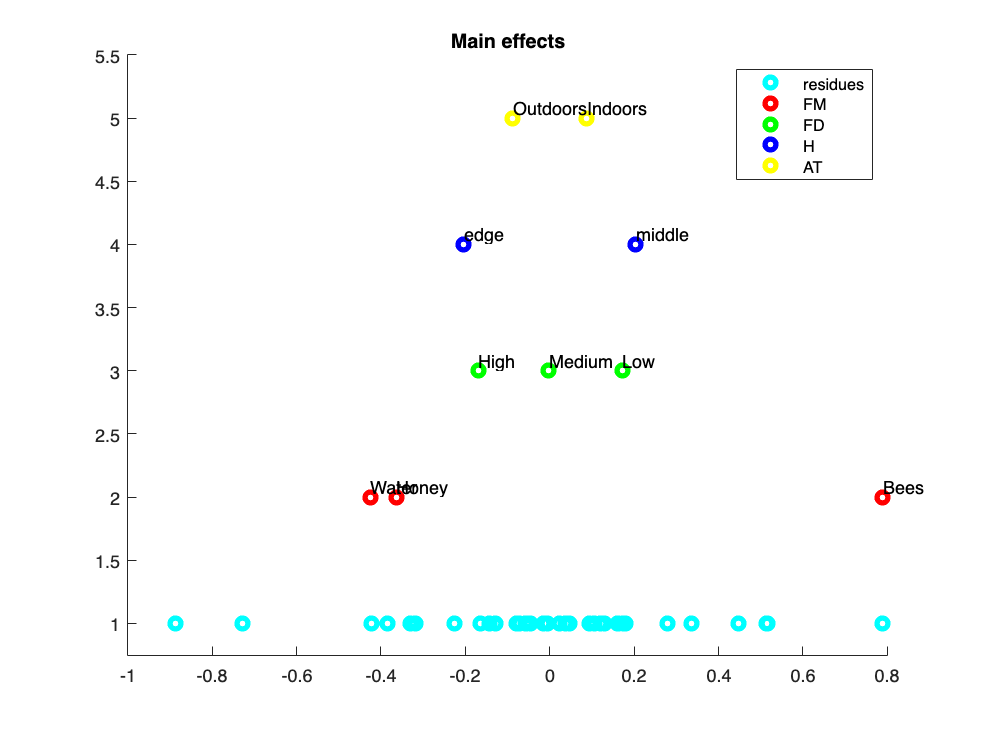

scatter(residuals_before_mixed,ones([1 height(residuals_before_mixed)]),"co","LineWidth",3)
hold on
scatter(FMMeans{:,3},2*ones([1 height(FMMeans)]),"ro","LineWidth",3)
scatter(FDMeans{:,3},3*ones([1 height(FDMeans)]),"go","LineWidth",3)
scatter(HMeans{:,3},4*ones([1 height(HMeans)]),"bo","LineWidth",3)
scatter(ATMeans{:,3},5*ones([1 height(ATMeans)]),"yo","LineWidth",3)
hold off
ylim([0.75 5.5])
%xlim([-80 80])
legend(["residues" "FM" "FD" "H" "AT"])
title("Main effects")
% Add labels
text(FMMeans{:,3}, 2*ones([1 height(FMMeans)]), FMMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(FDMeans{:,3}, 3*ones([1 height(FDMeans)]), FDMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(HMeans{:,3}, 4*ones([1 height(HMeans)]), HMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(ATMeans{:,3}, 5*ones([1 height(ATMeans)]), ATMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)

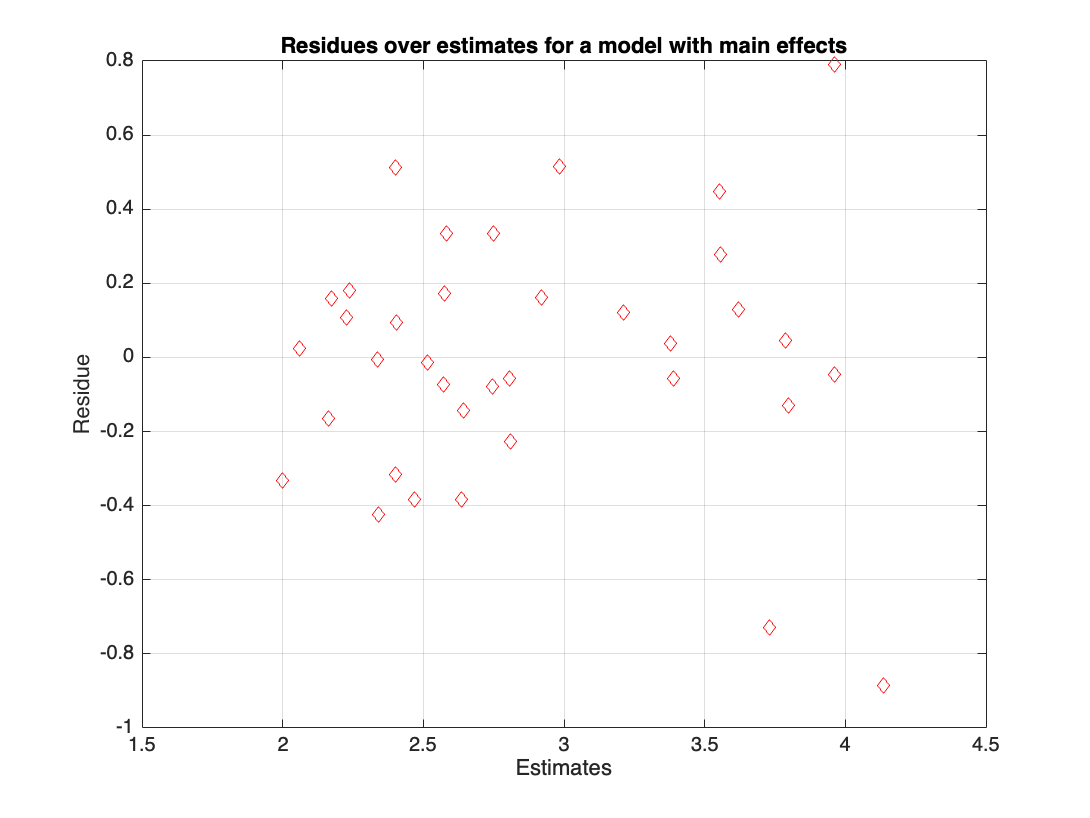



figure
plot(Estimates1,residuals_before_mixed,'rd')
title("Residues over estimates for a model with main effects")
xlabel('Estimates')
ylabel('Residue')
grid on

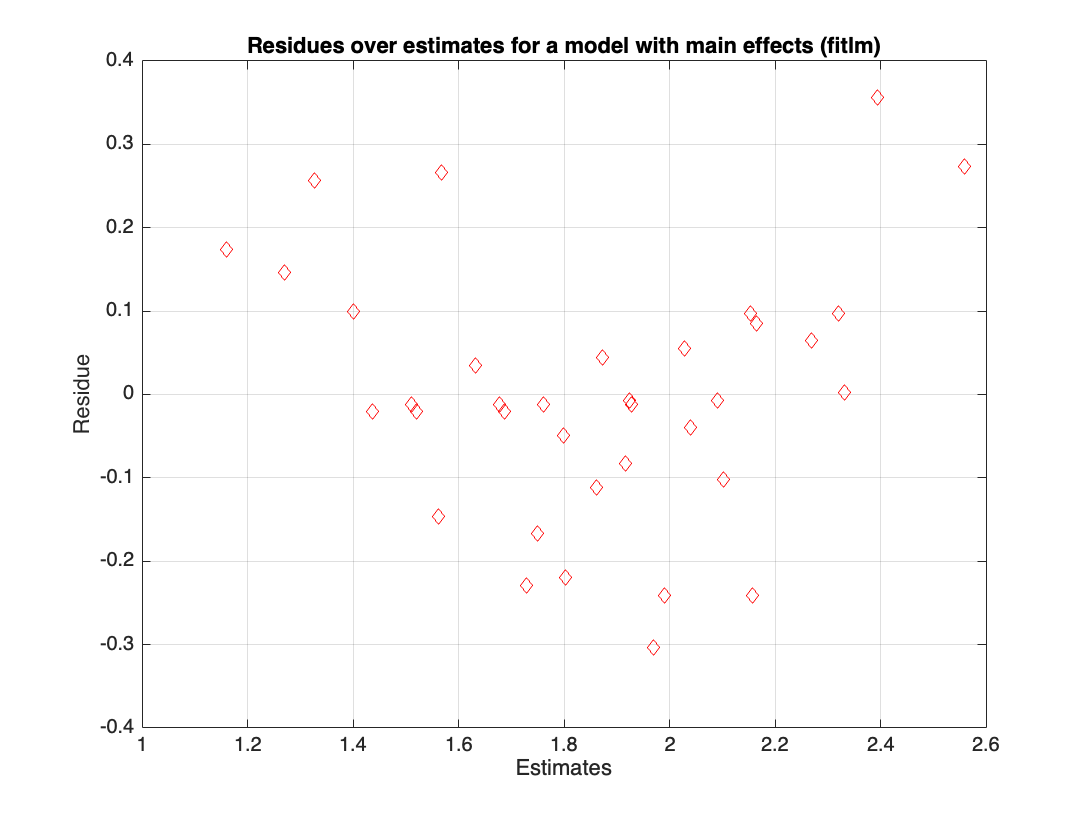

figure
plot(main_effects_model.Fitted,main_effects_model.Residuals.Raw,'rd')
title("Residues over estimates for a model with main effects (fitlm)")
xlabel('Estimates')
ylabel('Residue')
grid on

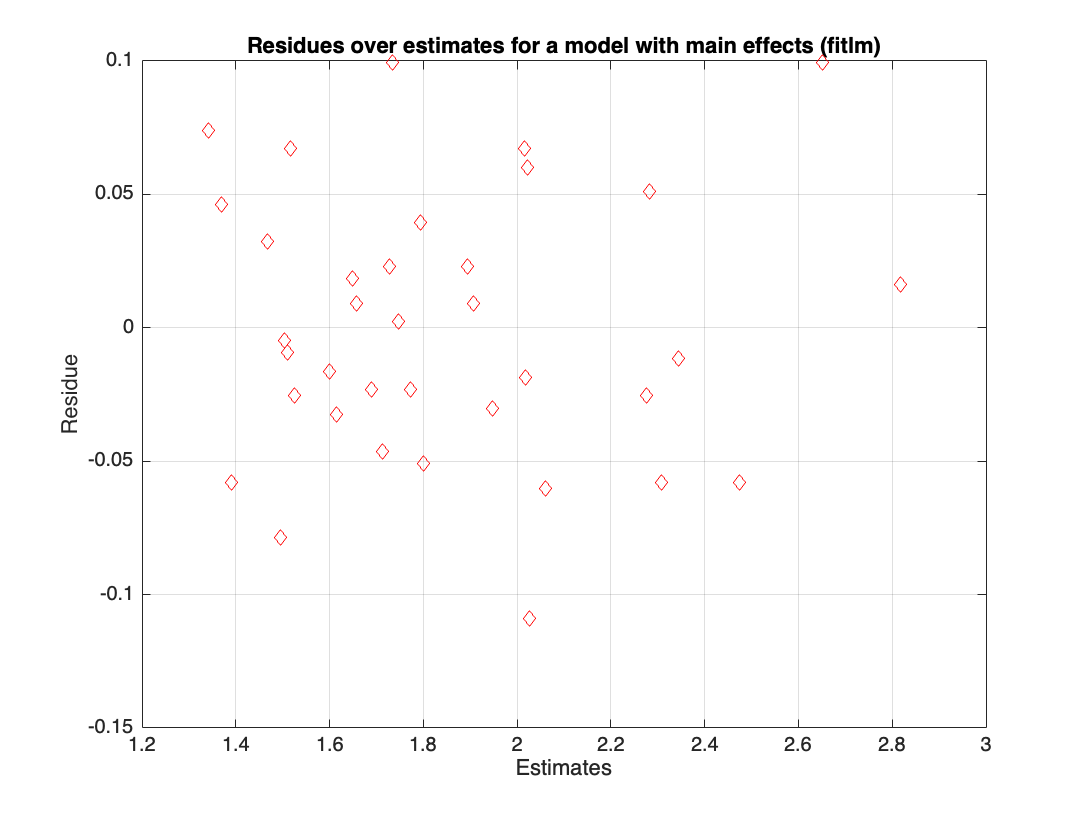

figure
plot(two_way_effects_model.Fitted,two_way_effects_model.Residuals.Raw,'rd')
title("Residues over estimates for a model with main effects (fitlm)")
xlabel('Estimates')
ylabel('Residue')
grid on

## Dot Plot with two-way mixed effects

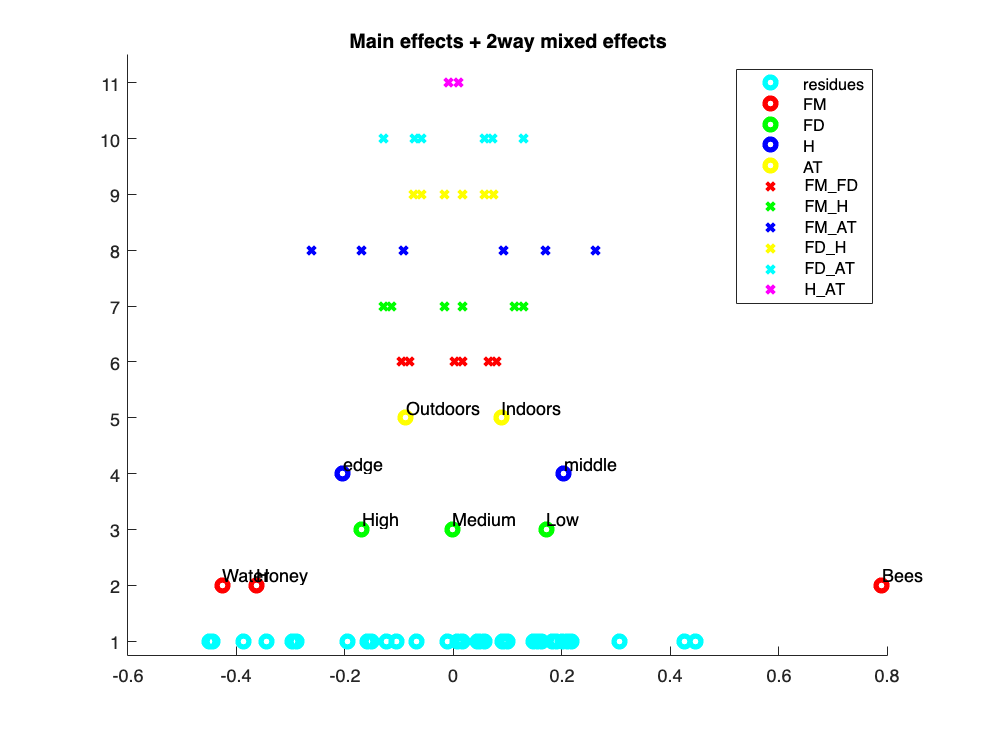

scatter(residuals_after_2way,ones([1 height(residuals_after_2way)]),"co","LineWidth",3)
hold on
scatter(FMMeans{:,3},2*ones([1 height(FMMeans)]),"ro","LineWidth",3)
scatter(FDMeans{:,3},3*ones([1 height(FDMeans)]),"go","LineWidth",3)
scatter(HMeans{:,3},4*ones([1 height(HMeans)]),"bo","LineWidth",3)
scatter(ATMeans{:,3},5*ones([1 height(ATMeans)]),"yo","LineWidth",3)
scatter(FM_FD{:,4},6*ones([1 height(FM_FD)]),"rx","LineWidth",2)
scatter(FM_H{:,4},7*ones([1 height(FM_H)]),"gx","LineWidth",2)
scatter(FM_AT{:,4},8*ones([1 height(FM_AT)]),"bx","LineWidth",2)
scatter(FD_H{:,4},9*ones([1 height(FD_H)]),"yx","LineWidth",2)
scatter(FD_AT{:,4},10*ones([1 height(FD_AT)]),"cx","LineWidth",2)
scatter(H_AT{:,4},11*ones([1 height(H_AT)]),"mx","LineWidth",2)
hold off
ylim([0.75 11.5])
legend(["residues" "FM" "FD" "H" "AT" "FM\_FD" "FM\_H" "FM\_AT" "FD\_H" "FD\_AT" "H\_AT"])
title("Main effects + 2way mixed effects")
% Add labels
text(FMMeans{:,3}, 2*ones([1 height(FMMeans)]), FMMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(FDMeans{:,3}, 3*ones([1 height(FDMeans)]), FDMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(HMeans{:,3}, 4*ones([1 height(HMeans)]), HMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(ATMeans{:,3}, 5*ones([1 height(ATMeans)]), ATMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)

## Dot Plot with three-way mixed effects

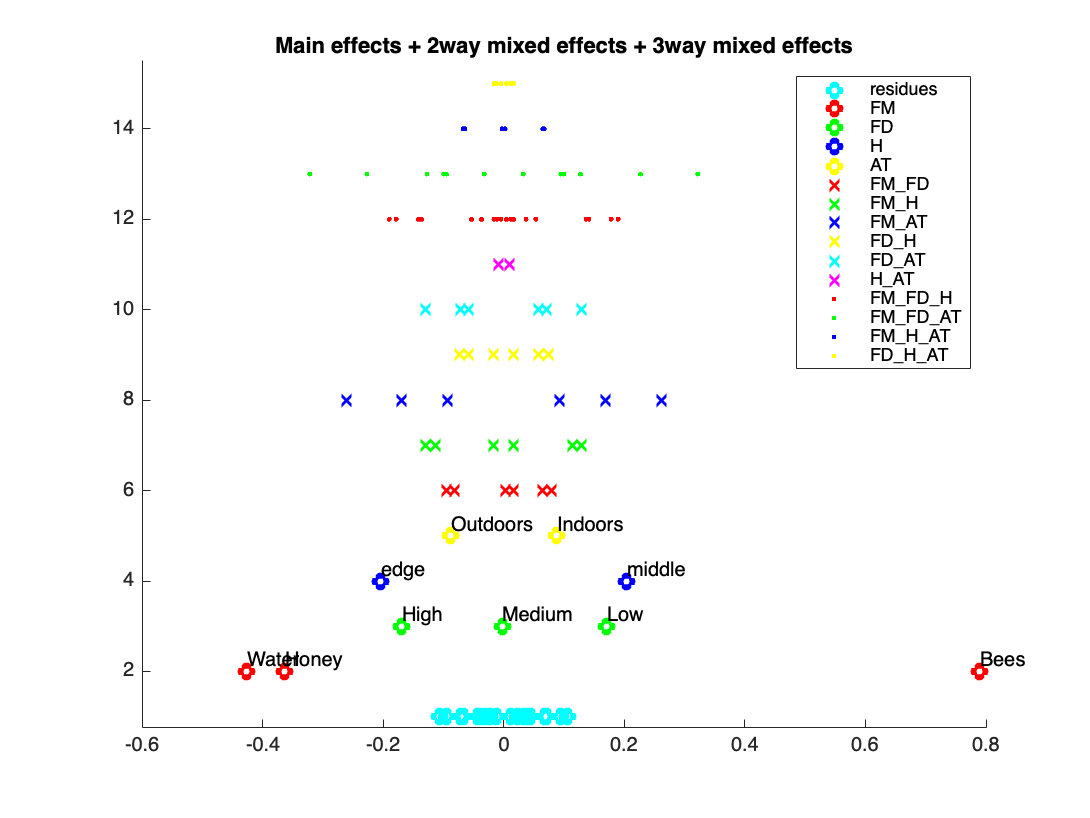

scatter(residuals_after_3way,ones([1 height(residuals_after_3way)]),"co","LineWidth",3)
hold on
scatter(FMMeans{:,3},2*ones([1 height(FMMeans)]),"ro","LineWidth",3)
scatter(FDMeans{:,3},3*ones([1 height(FDMeans)]),"go","LineWidth",3)
scatter(HMeans{:,3},4*ones([1 height(HMeans)]),"bo","LineWidth",3)
scatter(ATMeans{:,3},5*ones([1 height(ATMeans)]),"yo","LineWidth",3)
scatter(FM_FD{:,4},6*ones([1 height(FM_FD)]),"rx","LineWidth",2)
scatter(FM_H{:,4},7*ones([1 height(FM_H)]),"gx","LineWidth",2)
scatter(FM_AT{:,4},8*ones([1 height(FM_AT)]),"bx","LineWidth",2)
scatter(FD_H{:,4},9*ones([1 height(FD_H)]),"yx","LineWidth",2)
scatter(FD_AT{:,4},10*ones([1 height(FD_AT)]),"cx","LineWidth",2)
scatter(H_AT{:,4},11*ones([1 height(H_AT)]),"mx","LineWidth",2)
scatter(FM_FD_H{:,5},12*ones([1 height(FM_FD_H)]),"r.","LineWidth",5)
scatter(FM_FD_AT{:,5},13*ones([1 height(FM_FD_AT)]),"g.","LineWidth",5)
scatter(FM_H_AT{:,5},14*ones([1 height(FM_H_AT)]),"b.","LineWidth",5)
scatter(FD_H_AT{:,5},15*ones([1 height(FD_H_AT)]),"y.","LineWidth",5)
hold off
ylim([0.75 15.5])
legend(["residues" "FM" "FD" "H" "AT" "FM\_FD" "FM\_H" "FM\_AT" "FD\_H" "FD\_AT" "H\_AT" "FM\_FD\_H" "FM\_FD\_AT" "FM\_H\_AT" "FD\_H\_AT"])
title("Main effects + 2way mixed effects + 3way mixed effects")
% Add labels
text(FMMeans{:,3}, 2*ones([1 height(FMMeans)]), FMMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(FDMeans{:,3}, 3*ones([1 height(FDMeans)]), FDMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(HMeans{:,3}, 4*ones([1 height(HMeans)]), HMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(ATMeans{:,3}, 5*ones([1 height(ATMeans)]), ATMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)

## ANOVA

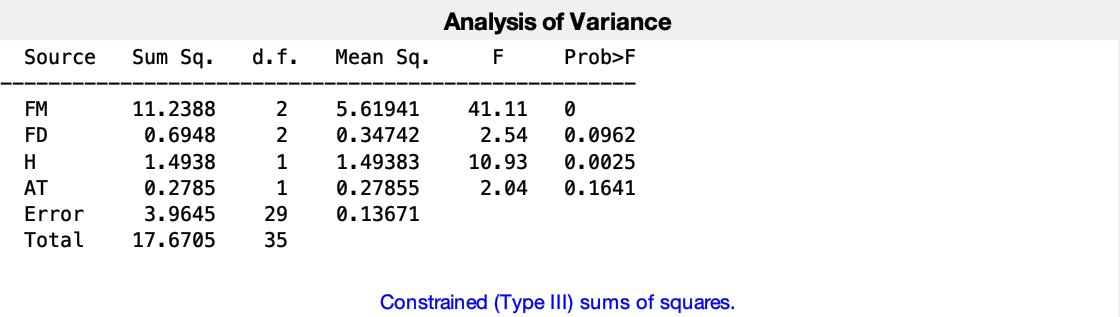

model_used=[1 0 0 0 ; 0 1 0 0 ; 0 0 1 0 ; 0 0 0 1; ... % Mains
           1 1 0 0 ; 1 0 1 0 ; 1 0 0 1 ; 0 1 1 0 ; 0 1 0 1 ; 0 0 1 1 ; ... % Two-ways
           1 1 1 0 ; 1 1 0 1 ; 1 0 1 1 ; 0 1 1 1 ;]; % Tree-ways
[p,tbl,stats] = anovan(data_full_fact{:,response_ix},{data_full_fact{:,1},data_full_fact{:,2},data_full_fact{:,3},data_full_fact{:,4}},'varnames',{'FM','FD','H','AT'},'model','linear');

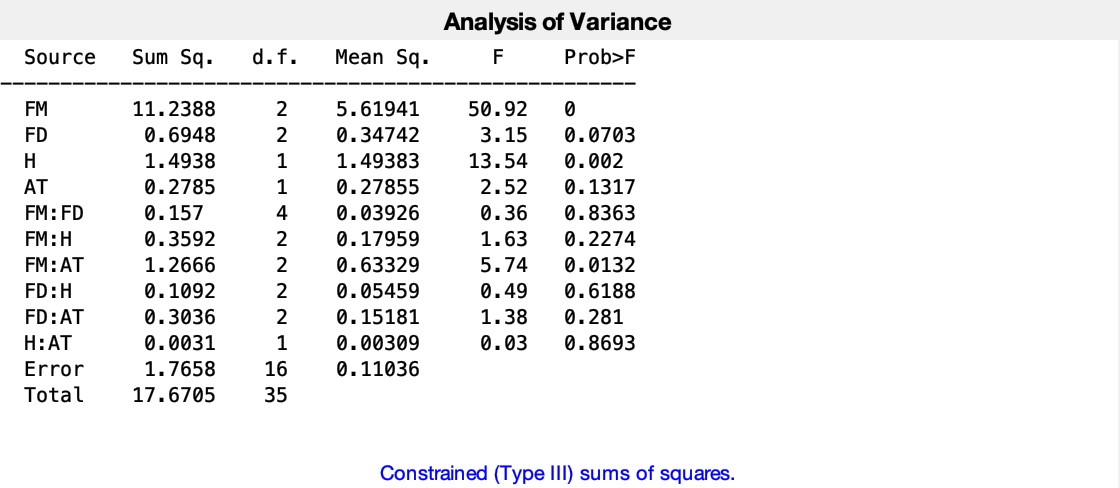

[p,tbl,stats] = anovan(data_full_fact{:,response_ix},{data_full_fact{:,1},data_full_fact{:,2},data_full_fact{:,3},data_full_fact{:,4}},'varnames',{'FM','FD','H','AT'},'model','interaction');

## Effect comparison

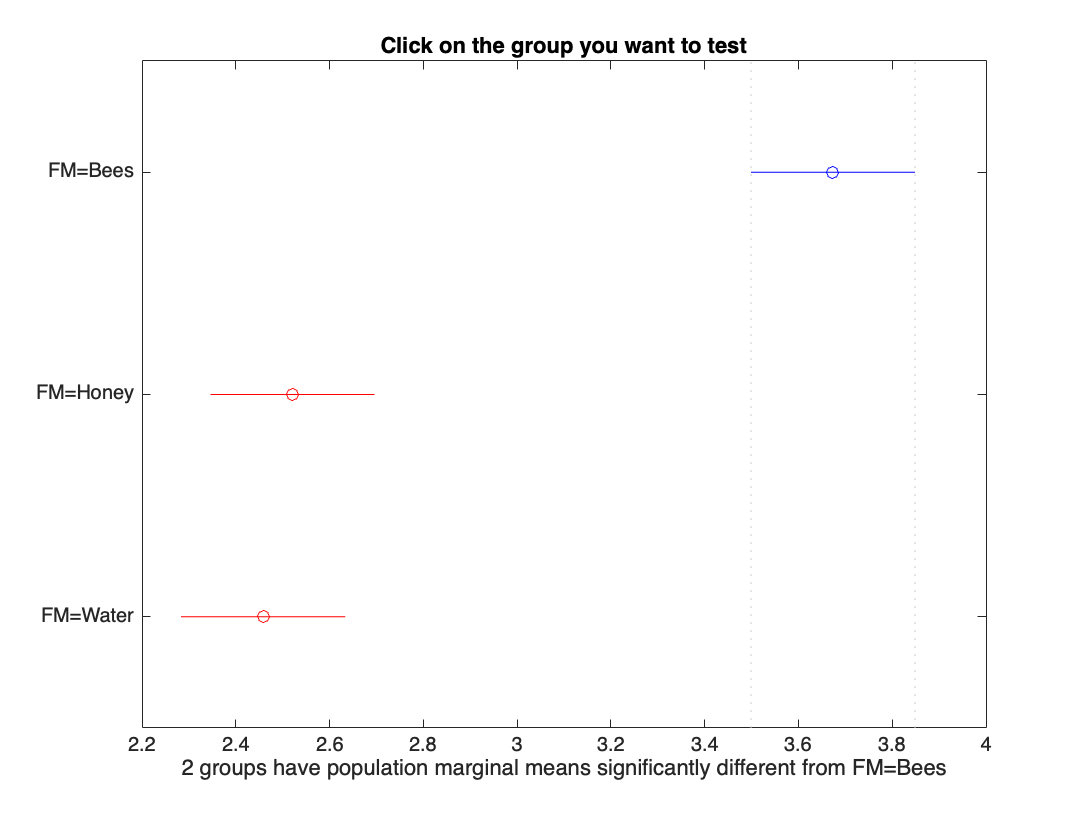

[comparison1,m1]=multcompare(stats,"Dimension",1,'Display','on');

Tcomparison=array2table(comparison1,"VariableNames",{'i','j','lim inf','delta','lim sup','p-value'});
disp(Tcomparison)

    i    j    lim inf     delta     lim sup     p-value  
    _    _    ________    ______    _______    __________

    1    2     0.80282    1.1528     1.5027    7.1845e-07
    1    3     0.86532    1.2153     1.5652    3.5513e-07
    2    3    -0.28746    0.0625    0.41246       0.89032



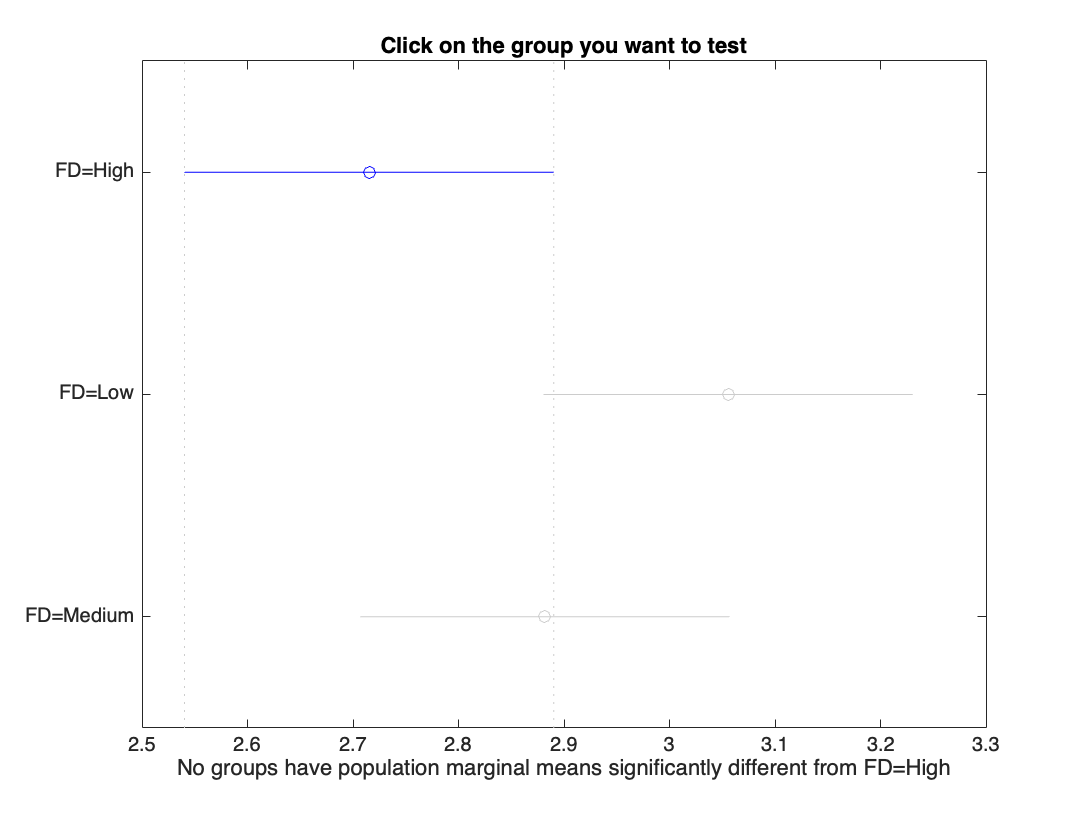


[comparison2,m2]=multcompare(stats,"Dimension",2,'Display','on');

Tcomparison=array2table(comparison2,"VariableNames",{'i','j','lim inf','delta','lim sup','p-value'});
disp(Tcomparison)

    i    j    lim inf      delta       lim sup     p-value 
    _    _    ________    ________    _________    ________

    1    2    -0.69023    -0.34028    0.0096777    0.057318
    1    3    -0.51662    -0.16667      0.18329       0.454
    2    3    -0.17634     0.17361      0.52357     0.42606



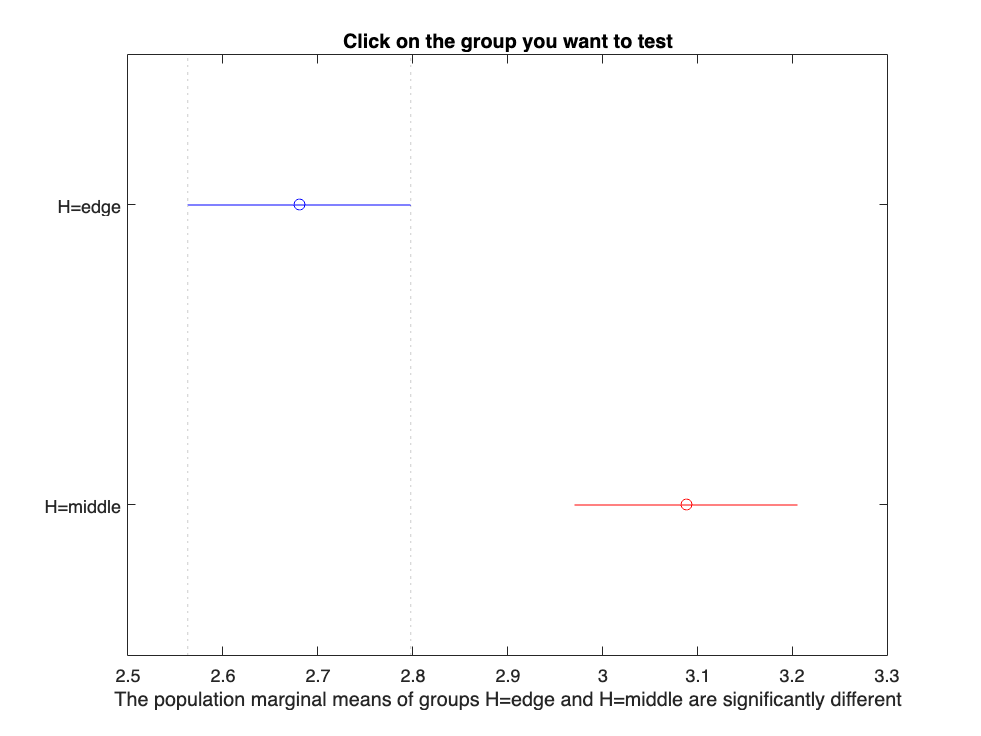


[comparison3,m3]=multcompare(stats,"Dimension",3,'Display','on');

Tcomparison=array2table(comparison3,"VariableNames",{'i','j','lim inf','delta','lim sup','p-value'});
disp(Tcomparison)

    i    j    lim inf      delta      lim sup      p-value 
    _    _    ________    ________    ________    _________

    1    2    -0.64216    -0.40741    -0.17266    0.0020302



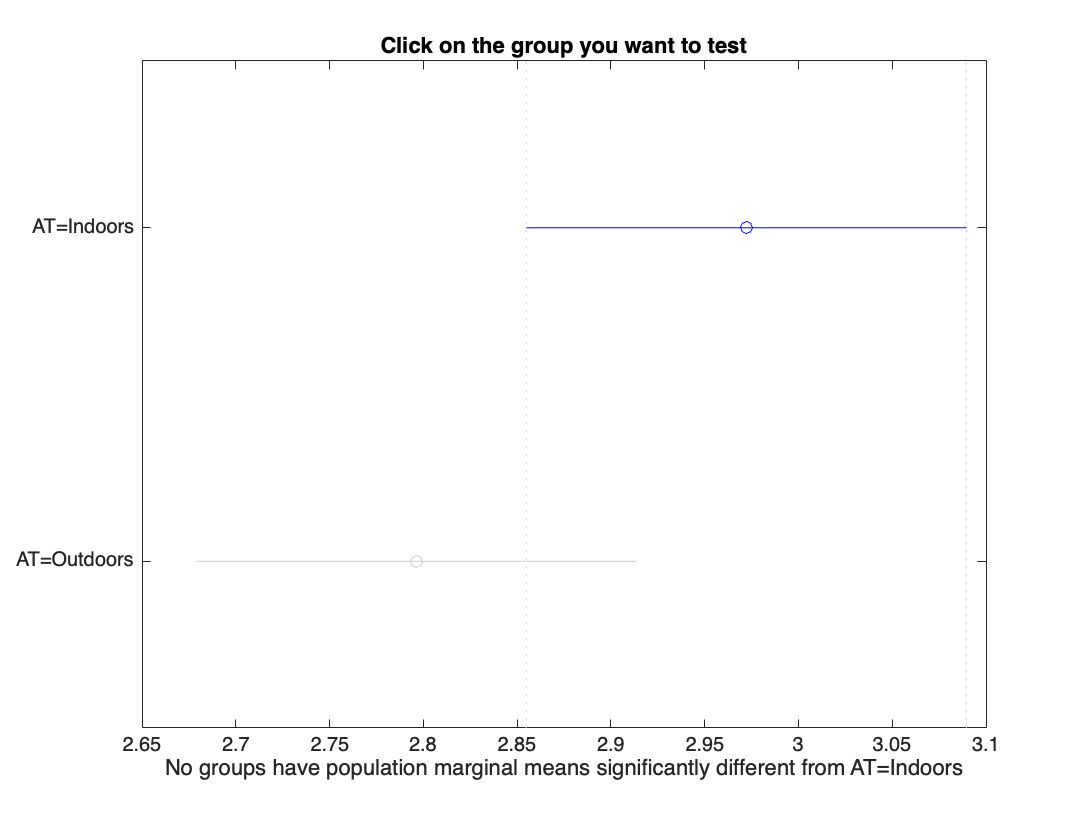


[comparison4,m4]=multcompare(stats,"Dimension",4,'Display','on');

Tcomparison=array2table(comparison3,"VariableNames",{'i','j','lim inf','delta','lim sup','p-value'});
disp(Tcomparison)

    i    j    lim inf      delta      lim sup      p-value 
    _    _    ________    ________    ________    _________

    1    2    -0.64216    -0.40741    -0.17266    0.0020302

